# Plotter

Ci-dessous des essais du 22/05/25

## Méthode classique

clear all
close all
folder_event = 'event';
folder_classic = 'classic';
base_path = '~/mecanum/csv/';
ev = [0.85 0.1 0.1];  % Rouge classique
cl = [0.1 0.7 0.1];
folders = {'classic', 'event'};
plot_gamma = false;


### Trajectoires

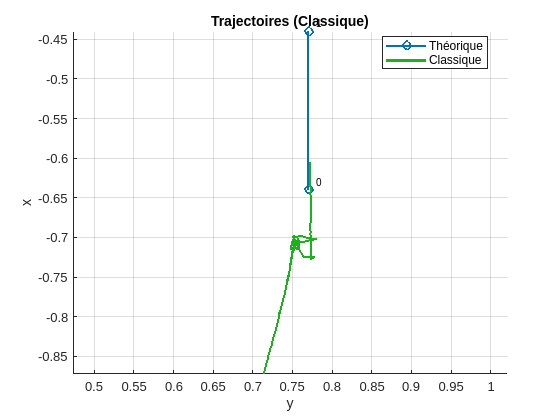

% === Lecture des trajectoires depuis les fichiers CSV ===
read_trajectory = @(folder) readtable(fullfile(base_path, folder, 'distributed_barycenter_logger.csv'));

data_classic = read_trajectory(folder_classic);

% === Nouvelle lecture de la trajectoire théorique depuis un fichier CSV ===
filename_theory = fullfile(base_path, folder_classic, 'distributed_goal_point_logger.csv');
data_theory = readtable(filename_theory);

X_th = data_theory.x;
Y_th = data_theory.y;

% === Extraction des trajectoires réelles ===
x_classic = data_classic.x;
y_classic = data_classic.y;


% === Tracé des trajectoires ===
figure;
hold on; grid on; axis equal;

% Trajectoire théorique
plot(-Y_th, X_th, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Théorique');
for i = 1:length(X_th)
    text(-Y_th(i)+0.01, X_th(i)+0.01, num2str(i-1), 'FontSize', 8);
end

% Trajectoire réelle (classique)
plot(-y_classic, x_classic, '-', 'Color', cl, 'LineWidth', 2, 'DisplayName', 'Classique');


xlabel('y');
ylabel('x');
title('Trajectoires (Classique)');
legend('Location', 'best');

Note : Dans le programme, on considère un point comme étant atteint si le barycentre de l'essaim est à 5cm de la cible, d'où les légers écarts avec les points-cibles.

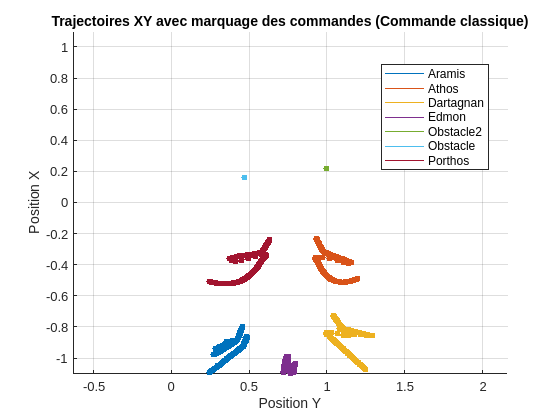

titles = {'Trajectoires XY avec marquage des commandes (Commande classique)'};

for k = 1:length(1)
    folder = folders{k};
    files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
    
    figure;
    hold on;
    axis equal;
    grid on;
    ylim([-1.1, 1.1]);  % Limites de l'axe Y

    
    colors = lines(length(files));
    legend_entries = {};
    plot_handles = gobjects(length(files),1);  % Pré-allocation des handles

    for i = 1:length(files)
        filename = fullfile(base_path, folder, files(i).name);
        data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');
        
        % Extraire les colonnes
        timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
        x = data{:,2};
        y = data{:,3};
        
        % Tracer la trajectoire (handle enregistré pour la légende)
        plot_handles(i) = plot(-y, x, '-', 'Color', colors(i,:), 'LineWidth', 0.8);
        
        % Marquer les moments de commande avec la même couleur que la courbe
        scatter(-y, x, 20, colors(i,:), 'filled', 'HandleVisibility', 'off');
        
        % Nom du robot
        robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
        legend_entries{end+1} = robot_name;
    end

    xlabel('Position Y');
    ylabel('Position X');
    title(titles{1});
    legend(plot_handles, legend_entries, 'Location', 'best');
end

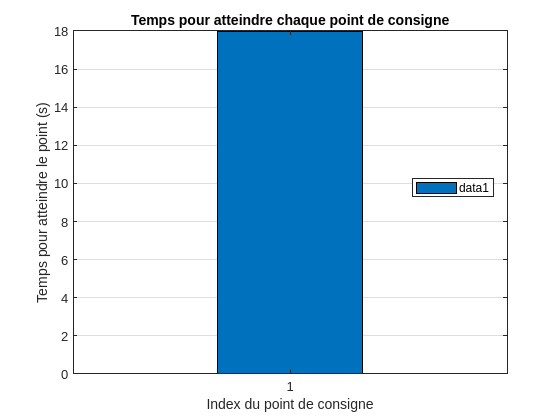


% === CLASSIC ===
folder = 'classic';
fichier_distance = fullfile(base_path, folder, 'distributed_distance_logger.csv');
fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');

% Lecture des données
data_classic = readtable(fichier_distance);
traj_classic = readtable(fichier_trajectoire);
time_abs_classic = datetime(data_classic{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
time_classic = seconds(time_abs_classic - time_abs_classic(1));
time_goal_classic = seconds(datetime(traj_classic{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs_classic(1));


% === Calcul des temps entre les points de consigne ===
delays_classic = diff(time_goal_classic);

% Limiter à la taille commune
n = length(delays_classic);
delays_classic = delays_classic(1:n);

% === Tracé en barplot avec couleurs personnalisées ===
figure;
b = bar([delays_classic], 'grouped');


xlabel('Index du point de consigne');
ylabel('Temps pour atteindre le point (s)');
legend('Location', 'best');
title('Temps pour atteindre chaque point de consigne');
grid on;


if plot_gamma
for k = 1:length(1)
    
    folder = folders{k};
    files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
    
    for f = 1:length(files)
        
        filepath = fullfile(files(f).folder, files(f).name);
        data = readtable(filepath);

        % Extraire les colonnes utiles
        t = data.timestamp - data.timestamp(1);  % temps en commençant à 0
        vx = data.linear_x;
        vy = data.linear_y;

        ui_gamma_x = data.ui_gamma_x;
        ui_gamma_y = data.ui_gamma_y;

        ui_alpha_x = data.ui_alpha_x;
        ui_alpha_y = data.ui_alpha_y;

        figure;
        
        % Subplot 1 : vx et vy
        subplot(3,1,1);
        hold on;
        plot(t, vx, 'DisplayName', 'vx');
        plot(t, vy, 'DisplayName', 'vy');
        xlabel('Temps (s)');
        ylabel('||v|| (m/s)');
        title(['Vitesses - ' files(f).name]);
        legend('Location', 'best');
        grid on;
        
        % Subplot 2 : ui_alpha_x et ui_alpha_y
        subplot(3,1,2);
        hold on;
        plot(t, ui_alpha_x, 'DisplayName', 'ui\_alpha\_x');
        plot(t, ui_alpha_y, 'DisplayName', 'ui\_alpha\_y');
        xlabel('Temps (s)');
        ylabel('ui_{\alpha} (m/s)');
        title(['ui_{\alpha}']);
        legend('Location', 'best');
        grid on;
        
        % Subplot 3 : ui_gamma_x et ui_gamma_y
        subplot(3,1,3);
        hold on;
        plot(t, ui_gamma_x, 'DisplayName', 'ui\_gamma\_x');
        plot(t, ui_gamma_y, 'DisplayName', 'ui\_gamma\_y');
        xlabel('Temps (s)');
        ylabel('ui_{\gamma} (m/s)');
        title(['ui_{\gamma} ' ]);
        legend('Location', 'best');
        grid on;

    end
end
end

### Distances

Ligne grise verticale : envoi d'un nouveau point-destination.

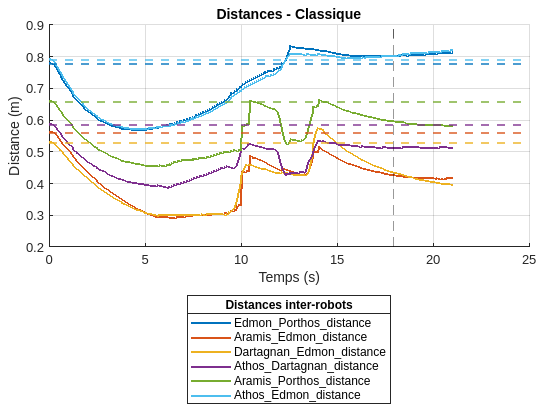

warning('off', 'all');

% === Tiled Layout ===
t = tiledlayout(1,1);  % un seul plot désormais
t.TileSpacing = 'compact';
t.Padding = 'compact';

% Subplot : Classique
nexttile;
hold on; grid on;
y_values = data_classic{1, 2:end};  % on ignore la 1re colonne (temps)

legend_handles = gobjects(width(data_classic)-1, 1);  % pour stocker les handles
for i = 2:width(data_classic)
    legend_handles(i-1) = plot(time_classic, data_classic{:,i}, ...
        'DisplayName', strrep(data_classic.Properties.VariableNames{i}, '_', '\_'), ...
        'LineWidth', 1.5);
end

for i = 1:length(y_values)
    yline(y_values(i), '--', ...
        'Color', legend_handles(i).Color, ...
        'LineWidth', 1.5);
end

for i = 2:length(time_goal_classic)
    xline(time_goal_classic(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

title('Distances - Classique');
xlabel('Temps (s)');
ylabel('Distance (m)');

% === Légende globale manuelle ===
% On crée une figure invisible temporaire pour créer la légende
fig_leg = figure('Visible', 'off');
ax = axes(fig_leg);
copyobj(legend_handles, ax);  % on copie les courbes
legend(ax, 'Orientation', 'horizontal', 'Location', 'southoutside');
lgd = legend(ax, 'show');
close(fig_leg);  % on ferme la figure temporaire

% Ajout de la légende globale à la figure principale
lgd = legend(legend_handles, 'Orientation', 'vertical', 'Location', 'southoutside');
lgd.Title.String = 'Distances inter-robots';

On note que les distances varient au lancement de l'algorithme, puis les robots convergent vers leurs positions voulues dans la formation (distance inter-robot relativement constante après que le premier point soit atteint)

### Commandes

%% Plotter : Visualisation des timestamps de commandes pour plusieurs robots

% Dossier contenant les CSV
files = dir(fullfile(base_path,folder, '*_cmd_vel_rate.csv'));

robot_names = {};
timestamp_counts = [];
timestamp_data = containers.Map;
dt_stats = containers.Map;

%% Lecture des fichiers de commandes
for i = 1:length(files)
    filename = fullfile(base_path,folder, files(i).name);
    data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');
    
    % Conversion des timestamps en datetime
    timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

    % Nom du robot (avant le suffixe)
    robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
    robot_names{end+1} = robot_name;

    % Temps relatif (temps 0 = premier timestamp)
    timestamps_rel = seconds(timestamps - timestamps(1));
    timestamp_data(robot_name) = timestamps_rel;
    timestamp_counts(end+1) = numel(timestamps_rel);

    % Étude statistique du delta t
    delta_t = seconds(diff(timestamps));
    stats.mean = mean(delta_t);
    stats.std = std(delta_t);
    stats.min = min(delta_t);
    stats.max = max(delta_t);
    dt_stats(robot_name) = stats;

    % Affichage dans la console
    fprintf('\nRobot: %s\n', robot_name);
    fprintf('  N = %d commandes\n', numel(timestamps));
    fprintf('  Δt moyen    : %.4f s\n', stats.mean);
    fprintf('  Δt min      : %.4f s\n', stats.min);
    fprintf('  Δt max      : %.4f s\n', stats.max);
    fprintf('  Δt ec type  : %.4f s\n', stats.std);
end


Robot: Aramis


  N = 211 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0962 s


  Δt max      : 0.1041 s


  Δt ec type  : 0.0009 s



Robot: Athos


  N = 211 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0931 s


  Δt max      : 0.1086 s


  Δt ec type  : 0.0016 s



Robot: Dartagnan


  N = 211 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0932 s


  Δt max      : 0.1064 s


  Δt ec type  : 0.0027 s



Robot: Edmon


  N = 211 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0922 s


  Δt max      : 0.1077 s


  Δt ec type  : 0.0037 s



Robot: Obstacle2


  N = 19197 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0428 s


  Δt max      : 0.1579 s


  Δt ec type  : 0.0051 s



Robot: Obstacle


  N = 19197 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0400 s


  Δt max      : 0.1603 s


  Δt ec type  : 0.0044 s



Robot: Porthos


  N = 211 commandes


  Δt moyen    : 0.1000 s


  Δt min      : 0.0940 s


  Δt max      : 0.1070 s


  Δt ec type  : 0.0021 s


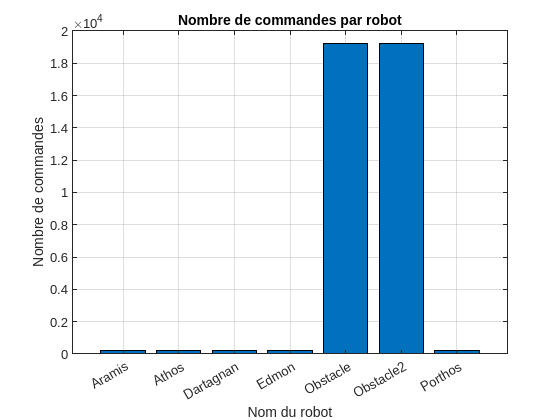


%% Figure 1 : Histogramme (bar chart)
figure;
bar(categorical(robot_names), timestamp_counts);
xlabel('Nom du robot');
ylabel('Nombre de commandes');
title('Nombre de commandes par robot');
grid on;

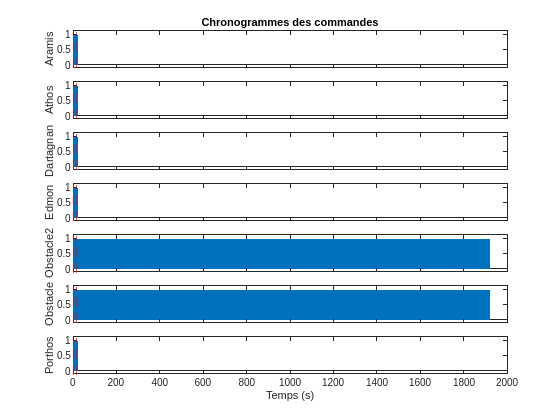


%% Lecture des points de trajectoire (pour les lignes verticales)

% Lire le CSV avec noms de colonnes
traj_data = readtable(fichier_trajectoire, 'Delimiter', ',', 'ReadVariableNames', true);
raw_timestamps = traj_data{:, 1};  % première colonne
goal_times = datetime(raw_timestamps, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
goal_times_rel = seconds(goal_times - goal_times(1));  % Temps relatif

%% Figure 2 : Chronogrammes par robot (subplots synchronisés)
figure;
n = length(robot_names);

% Fusionner tous les temps relatifs uniques
all_times = [];
for i = 1:n
    all_times = [all_times; timestamp_data(robot_names{i})];
end
all_times = unique(all_times);

% Subplots : chronogramme binaire pour chaque robot
for i = 1:n
    ax = subplot(n, 1, i);
    timestamps = timestamp_data(robot_names{i});
    y = ismember(all_times, timestamps);
    stem(all_times, y, 'Marker', 'none', 'LineWidth', 1.2);
    ylim([-0.1, 1.1]);
    ylabel(robot_names{i});
    if i == 1
        title('Chronogrammes des commandes');
    end
    if i < n
        set(gca, 'XTickLabel', []);
    else
        xlabel('Temps (s)');
    end
end

% Ajouter les lignes verticales pour les changements de consigne
for i = 1:n
    subplot(n, 1, i);
    hold on;
    for t = goal_times_rel'
        xline(t, '--r', 'LineWidth', 1);
    end
end